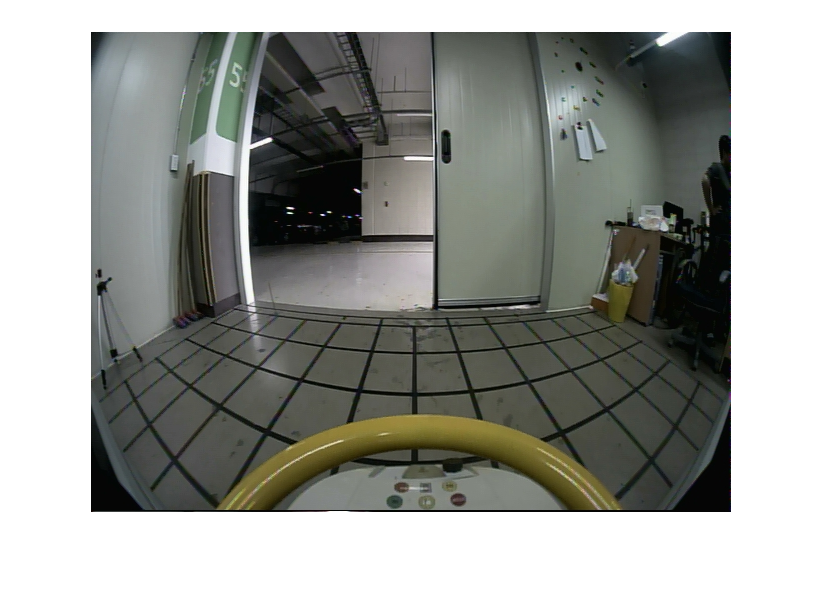

close all; clear; clc;
load('cameraParams.mat');
img_front = imread('front.jpg');
img_back = imread('back.jpg');
img_right = imread('right.jpg');
img_left = imread('left.jpg');
img_car = imread('car.bmp');
IC = imresize(img_car, [480 180]);

figure(); imshow(img_front);

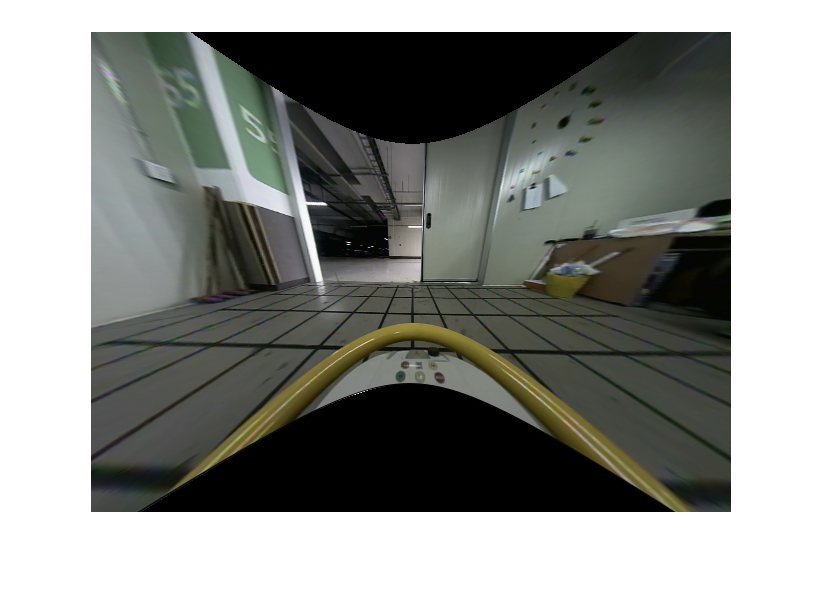


JF = undistortFisheyeImage(img_front,cameraParams.Intrinsics,'ScaleFactor',0.35);
JB = undistortFisheyeImage(img_back,cameraParams.Intrinsics,'ScaleFactor',0.35);
JB = rot90(JB,2); %후방
JR = undistortFisheyeImage(img_right,cameraParams.Intrinsics,'ScaleFactor',0.21);
JR = rot90(JR,-1); %우
JL = undistortFisheyeImage(img_left,cameraParams.Intrinsics,'ScaleFactor',0.21);
JL = rot90(JL,1); %좌
figure(); imshow(JF);

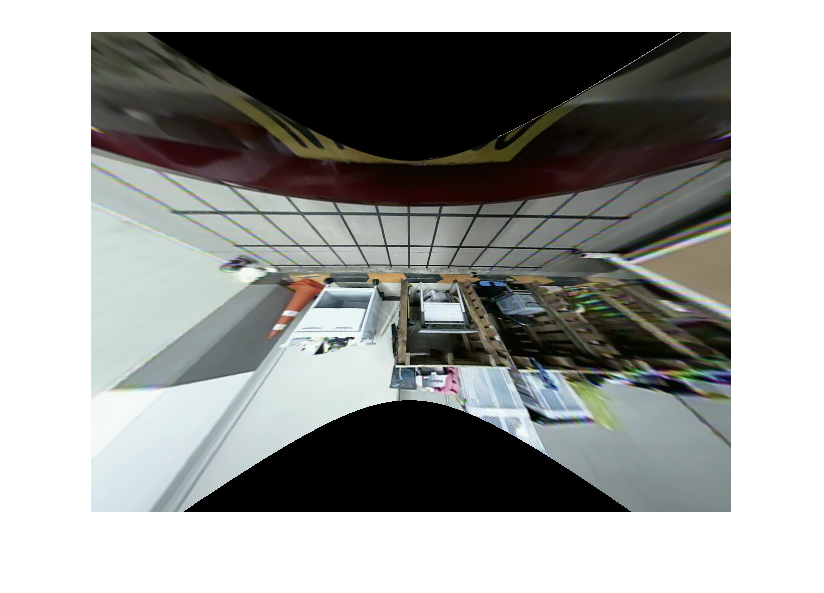

figure(); imshow(JB);

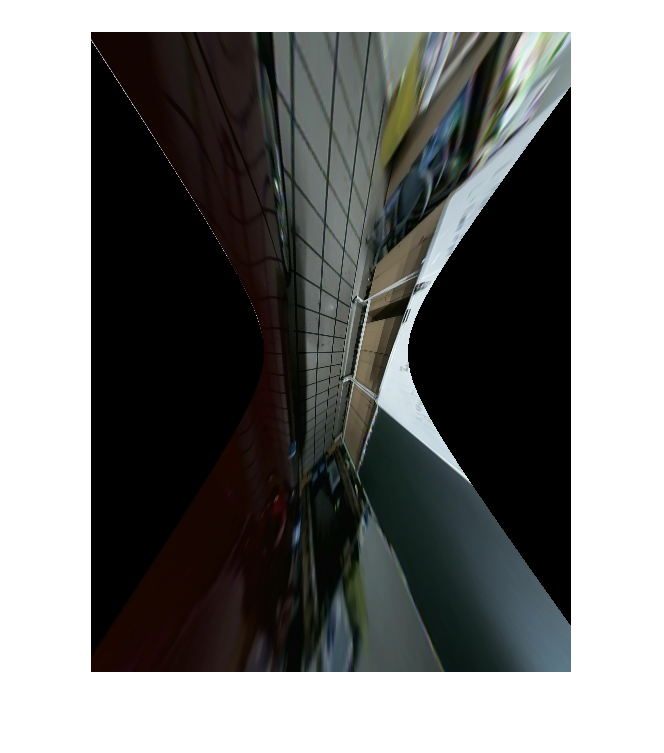

figure(); imshow(JR);

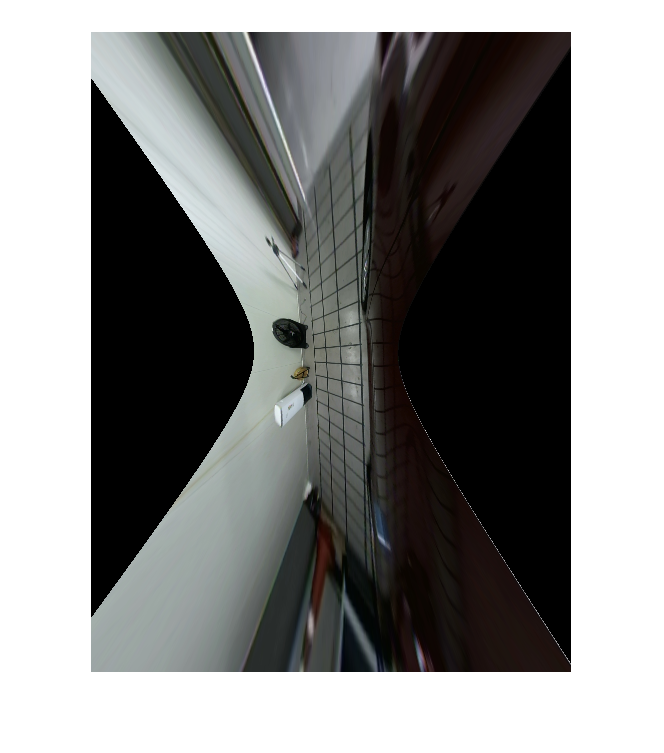

figure(); imshow(JL);

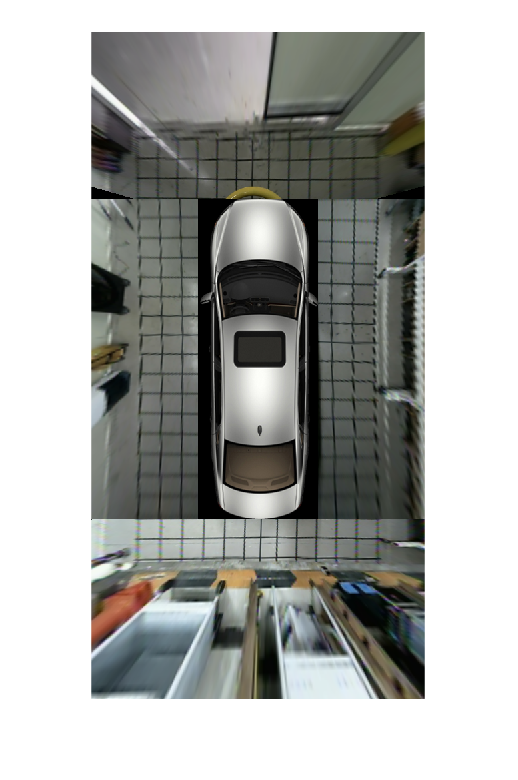


FA = [213 254; 438 258; 523 284; 131 278];%앞
FB = [70 160; 430 160; 430 220; 70 220];
BA = [85 181; 534 187; 448 236; 182 233]; %뒤
BB = [70 0; 430 0; 430 60; 70 60];
RA = [218 38; 275 181; 242 402; 213 431]; %우
RB = [0 0; 90 0; 90 480; 0 480];
LA = [217 231; 260 179; 270 498; 230 445];%좌
LB = [70 0; 160 0; 160 480; 70 480];


final_image = uint8(zeros(1000,500,3)); % 최종 이미지 틀


TF = fitgeotrans(FA, FB, 'projective');
TB = fitgeotrans(BA, BB, 'projective');
TR = fitgeotrans(RA, RB, 'projective');
TL = fitgeotrans(LA, LB, 'projective');

I_ref_F = imref2d([250 500]);
IF = imwarp(JF, TF, 'OutputView', I_ref_F);
I_ref_B = imref2d([270 500]);
IB = imwarp(JB, TB, 'OutputView', I_ref_B);
I_ref_R = imref2d([480 160]);
IR = imwarp(JR, TR, 'OutputView', I_ref_R);
I_ref_L = imref2d([480 160]);
IL = imwarp(JL, TL, 'OutputView', I_ref_R);

%변환한 이미지를 최종 이미지의 자리에 끼워넣는다.
final_image(1:250, 1:500, 1:3) = IF;
final_image(731:1000, 1:500, :) = IB;
final_image(251:730, 341:500, :) = IR;
final_image(251:730, 1:160, :) = IL;
final_image(251:730, 161:340, :) = IC;

figure(); imshow(final_image);